load stef_fig_compute.mat

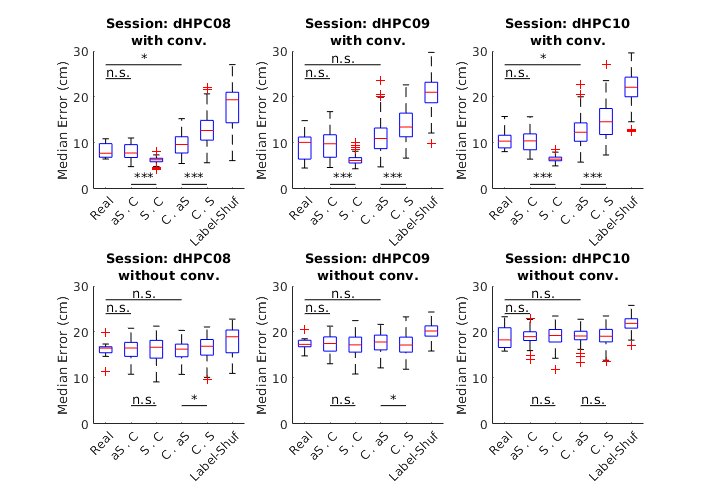

%figure('Position', [103         154        1221         726]);
figure('Position', [216   270   712   496]);
gap = 1.5;
for i = 1:3
    megares_conv = res_fs(i).conv;
    megares_noconv = res_fs(i).noconv;
    
    bp = comp_struct(megares_conv);
    bp.real = bp.real(1:10);
    bp_noconv = comp_struct(megares_noconv);
    bp_noconv.real = bp_noconv.real(1:10);

    subplot(2,3,i);
    signif_multibox({bp.real, bp.asoc, bp.soc, bp.coas, bp.cos, bp.labelshuf},...
        {'Real', 'aS . C', 'S . C', 'C . aS', 'C . S', 'Label-Shuf'},...
        {{'Real', 'aS . C'}, {'Real', 'C . aS'}, {'aS . C', 'S . C'}, {'C . aS', 'C . S'}},...
        [24 27 1 1], gap);
    ylim([0 30]);
    ylabel 'Median Error (cm)'
    
    label = split(fs_sess{i}.id, '_');
    label = label{1}(5:6);
    title(sprintf('Session: dHPC%s\nwith conv.', label));
    box off
    
    subplot(2,3,i+3);
    bp = bp_noconv;
    signif_multibox({bp.real, bp.asoc, bp.soc, bp.coas, bp.cos, bp.labelshuf},...
        {'Real', 'aS . C', 'S . C', 'C . aS', 'C . S', 'Label-Shuf'},...
        {{'Real', 'aS . C'}, {'Real', 'C . aS'}, {'aS . C', 'S . C'}, {'C . aS', 'C . S'}},...
        [24 27 4 4], gap);
    ylim([0 30]);
    ylabel 'Median Error (cm)'

    label = split(fs_sess{i}.id, '_');
    label = label{1}(5:6);
    title(sprintf('Session: dHPC%s\nwithout conv.', label));
    box off
end
Utils.printto('events_figs/stef_fig', 'fs_result.pdf');

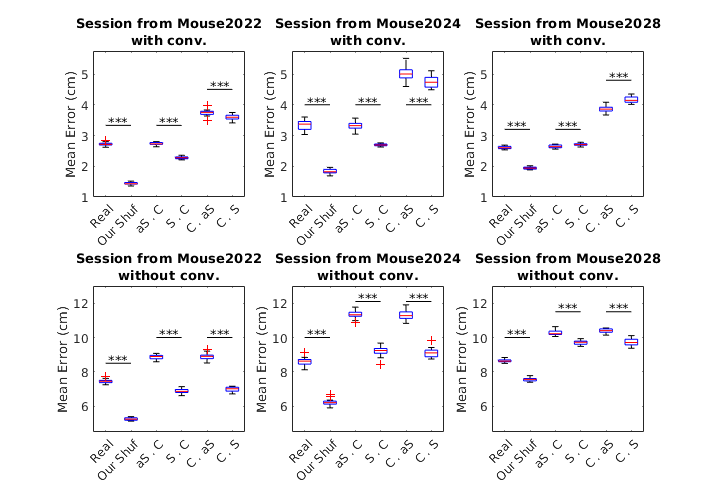

%figure('Position', [173         191        1280         795]);
figure('Position', [216   270   712   496]);
m_names = {'Mouse2022', 'Mouse2024', 'Mouse2028'};
line_pos = {[3.33 3.33 4.5], [4 4 4], [3.2 3.2 4.8]};
line_pos_nc = {[8.5 10 10], [10 12.1, 12.1], [10 11.5 11.5]};
for i = 1:3
    res_linear = res_us(i).conv;
    bp_lin = comp_struct_alt(res_linear);
    
    subplot(2,3,i);
    signif_multibox({bp_lin.real, bp_lin.inshuf, bp_lin.asoc, bp_lin.soc, bp_lin.coas, bp_lin.cos},...
    {'Real', 'Our Shuf', 'aS . C', 'S . C', 'C . aS', 'C . S'},...
    {{'Real', 'Our Shuf'}, {'aS . C', 'S . C'}, {'C . aS', 'C . S'}},...
    line_pos{i}, 0.1);
    ylim([1 5.75]);
    ylabel 'Mean Error (cm)'
    title(sprintf('Session from %s\nwith conv.', m_names{i}));
    
    res_linear = res_us(i).noconv;
    bp_lin = comp_struct_alt(res_linear);
    
    subplot(2,3,i+3);
    signif_multibox({bp_lin.real, bp_lin.inshuf, bp_lin.asoc, bp_lin.soc, bp_lin.coas, bp_lin.cos},...
    {'Real', 'Our Shuf', 'aS . C', 'S . C', 'C . aS', 'C . S'},...
    {{'Real', 'Our Shuf'}, {'aS . C', 'S . C'}, {'C . aS', 'C . S'}},...
    line_pos_nc{i}, 0.2);
    ylim([4.5 13]);
    ylabel 'Mean Error (cm)'
    title(sprintf('Session from %s\nwithout conv.', m_names{i}));
end
Utils.printto('events_figs/stef_fig', 'us_result.pdf');

function s_out = comp_struct(s_in)
F = fields(s_in);
for i = 1:numel(F)
    f = F{i};
    s_out.(f) = vertcat(s_in.(f));
end
end

function s_out = comp_struct_alt(s_in)
F = fields(s_in);
for i = 1:numel(F)
    f = F{i};
    s_out.(f) = horzcat(s_in.(f)).';
end
end